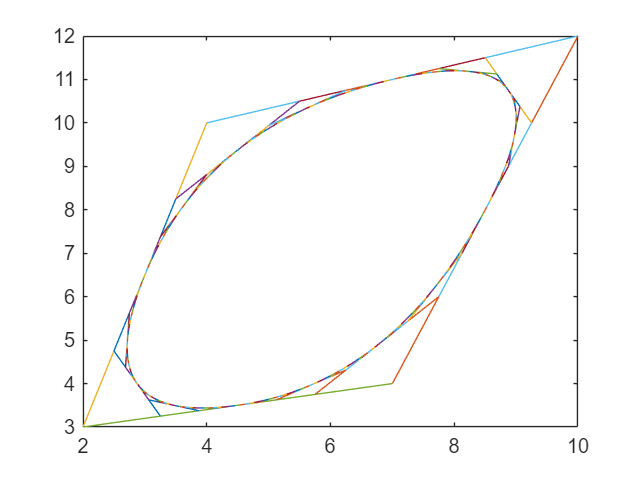

clc
clear
close
n=7;
x=[2,4,10,7];
y=[3,10,12,4];
num=length(x);
arrayX=cell(1,n);
arrayY=cell(1,n);
arrayX{1}=x;
arrayY{1}=y;
for i=2:n
    for j=1:num*power(2,i-2)-1
        arrayX{i}=[arrayX{i},arrayX{i-1}(j)*3/4+arrayX{i-1}(j+1)/4];
        arrayX{i}=[arrayX{i},arrayX{i-1}(j)/4+arrayX{i-1}(j+1)*3/4];
    end
    arrayX{i}=[arrayX{i},arrayX{i-1}(j+1)*3/4+arrayX{i-1}(1)/4];
    arrayX{i}=[arrayX{i},arrayX{i-1}(j+1)/4+arrayX{i-1}(1)*3/4];
end
for i=2:n
    for j=1:num*power(2,i-2)-1
        arrayY{i}=[arrayY{i},arrayY{i-1}(j)*3/4+arrayY{i-1}(j+1)/4];
        arrayY{i}=[arrayY{i},arrayY{i-1}(j)/4+arrayY{i-1}(j+1)*3/4];
    end
    arrayY{i}=[arrayY{i},arrayY{i-1}(j+1)*3/4+arrayY{i-1}(1)/4];
    arrayY{i}=[arrayY{i},arrayY{i-1}(j+1)/4+arrayY{i-1}(1)*3/4];
end
for i=1:n
    for j=1:num*power(2,i-1)-1
        plot(arrayX{i}(j),arrayY{i}(j),arrayX{i}(j+1),arrayY{i}(j+1));
        line([arrayX{i}(j),arrayX{i}(j+1)],[arrayY{i}(j),arrayY{i}(j+1)]);
        hold on;
    end
    plot(arrayX{i}(j+1),arrayY{i}(j+1),arrayX{i}(1),arrayY{i}(1));
    line([arrayX{i}(j+1),arrayX{i}(1)],[arrayY{i}(j+1),arrayY{i}(1)]);
    hold on;
end